# ARIMA MODEL

## Creating the ARIMAX Model

Predictions_ARIMAX_2023 = zeros([],[]);

random_data_matrix_transposed = random_data_matrix'; 
%X = random_data_matrix_transposed(:,2:end);
X = random_data_matrix_transposed;

T = size(random_data_matrix_transposed,1);
time_to_estimate = 15;
idxpresample = 1:4;
idxestimate = 5:time_to_estimate;
idxforecast = (time_to_estimate+1):T;
% time_to_estimate = 7;
% idxpresample = 1:2;
% idxestimate = 3:time_to_estimate;
% idxforecast = (time_to_estimate+1):T;
t = 1:96;

Mdl_origin = arima(2,0,1);


for idx = 1 : size(data_matrix_2023,1)

    day_to_predict =  (data_matrix_2023(idx,:))';

    y0est = day_to_predict(idxpresample); % Presample response data for estimation
    yest = day_to_predict(idxestimate);   % Response data for estimation
    XEst = X(idxestimate,:);     % Estimation sample exogenous data
    
    Mdl = estimate(Mdl_origin,yest,'Y0',y0est,'X',XEst,'Display','off');
    y0f = yest((end - 2):end); % Presample response data for forecasting
    X0f = XEst((end - 1):end,:); % Presample exogenous data for forecasting
    XF = X(idxforecast,:);     % Forecast period exogenous data for model regression component
    idx
    Predictions_ARIMAX_2023(:,idx) = forecast(Mdl,T-time_to_estimate,y0f,'X0',X0f,'XF',XF);
end

idx = 1

idx = 2

idx = 3

idx = 4

idx = 5

idx = 6

idx = 7

idx = 8

idx = 9

idx = 10

idx = 11

idx = 12

idx = 13

idx = 14

idx = 15

idx = 16

idx = 17

idx = 18

idx = 19

idx = 20

idx = 21

idx = 22

idx = 23

idx = 24

idx = 25

idx = 26

idx = 27

idx = 28

idx = 29

idx = 30

idx = 31

idx = 32

idx = 33

idx = 34

idx = 35

idx = 36

idx = 37

idx = 38

idx = 39

idx = 40

idx = 41

idx = 42

idx = 43

idx = 44

idx = 45

idx = 46

idx = 47

idx = 48

idx = 49

idx = 50

idx = 51

idx = 52

idx = 53

idx = 54

idx = 55

idx = 56

idx = 57

idx = 58

idx = 59

idx = 60

idx = 61

idx = 62

idx = 63

idx = 64

idx = 65

idx = 66

idx = 67

idx = 68

idx = 69

idx = 70

idx = 71

idx = 72

idx = 73

idx = 74

idx = 75

idx = 76

idx = 77

idx = 78

idx = 79

idx = 80

idx = 81

idx = 82

idx = 83

idx = 84

idx = 85

## Normalize 2023

% mu2023 = mean(cat(2,data_matrix_2023_Cell{:}),2);
% sigma2023 = std(cat(2,data_matrix_2023_Cell{:}),0,2);
% 
% data_matrix_2023 = (data_matrix_2023 - mu2023) ./ sigma2023;


## Normalize ARIMA Prediction

Predictions_ARIMAX_2023_transposed = Predictions_ARIMAX_2023';
%rowDist_arima = ones(1,length(Predictions_ARIMAX_2023_transposed));
rowDist_arima = ones(1,size(Predictions_ARIMAX_2023_transposed,1));

Predictions_ARIMAX_2023_transposed_Cell = mat2cell(Predictions_ARIMAX_2023_transposed,rowDist_arima);

mu_arima = mean(cat(2,Predictions_ARIMAX_2023_transposed_Cell{:}),2);
sigma_arima = std(cat(2,Predictions_ARIMAX_2023_transposed_Cell{:}),0,2);

Predictions_ARIMAX_2023_transposed = (Predictions_ARIMAX_2023_transposed - mu_arima) ./ sigma_arima;

## Plot for Example Prediction Vs. Real

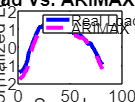

offset = 15;
chosen = 57;
t_arima = 1:96-offset;
figure;
plot(t_arima,data_matrix_2023_NORMALIZED(chosen,offset+1:end),"b","LineWidth",2);
hold on
plot(t_arima,Predictions_ARIMAX_2023_transposed(chosen,:),"m--","LineWidth",2);

title('Real Load Vs. ARIMAX Forcast');
legend('Real Load','ARIMAX Forcast');
xlabel('Samples')
ylabel('Normalized Load');

## 'Shortest Path' on Prediction and Real G

% 
% Shortest_on_pred_ARIMAX_2023 = zeros([],[]);
% Shorters_on_real_G_ARIMAX_2023 = zeros([],[]);
% 
% offset = 20;
% E_max = 4e4;
% 
% for idx = 1 : 2 %%size(data_matrix_2023,1)
%     print = 0;
%     Shortest_on_pred_ARIMAX_2023(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
%     Shorters_on_real_G_ARIMAX_2023(idx,:) = YES_shortest_on_prediction_fnc(data_matrix_2023_NORMALIZED(offset + 1,:),sigma2023,mu2023,E_max,print);
% 
% end
% 
% print = 1;
% Shortest_on_pred_ARIMAX_2023(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
% Shorters_on_real_G_ARIMAX_2023(idx,:) = YES_shortest_on_prediction_fnc(data_matrix_2023_NORMALIZED(offset + 1,:),sigma2023,mu2023,E_max,print);

Shorters_on_real_G_ARIMAX_2023_E5 = zeros([],[]);
Shortest_on_pred_ARIMAX_2023_E5 = zeros([],[]);

Shorters_on_real_G_ARIMAX_2023_E10 = zeros([],[]);
Shortest_on_pred_ARIMAX_2023_E10 = zeros([],[]);

Shorters_on_real_G_ARIMAX_2023_E20 = zeros([],[]);
Shortest_on_pred_ARIMAX_2023_E20 = zeros([],[]);

Shorters_on_real_G_ARIMAX_2023_E30 = zeros([],[]);
Shortest_on_pred_ARIMAX_2023_E30 = zeros([],[]);

Shorters_on_real_G_ARIMAX_2023_E40 = zeros([],[]);
Shortest_on_pred_ARIMAX_2023_E40 = zeros([],[]);

Shorters_on_real_G_ARIMAX_2023_E100 = zeros([],[]);
Shortest_on_pred_ARIMAX_2023_E100 = zeros([],[]);


offset = 15;

for i = 1:size(energy_sizes_percentage,2)
    print = 0;

    switch i

        case 1
            E_max = Storage_size(1);
            for idx = 1 : size(data_matrix_2023,1)
                day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
                Shortest_on_pred_ARIMAX_2023_E5(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
                Shorters_on_real_G_ARIMAX_2023_E5(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 2
            E_max = Storage_size(2);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_ARIMAX_2023_E10(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
            Shorters_on_real_G_ARIMAX_2023_E10(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 3
            E_max = Storage_size(3);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_ARIMAX_2023_E20(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
            Shorters_on_real_G_ARIMAX_2023_E20(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 4
            E_max = Storage_size(4);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_ARIMAX_2023_E30(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
            Shorters_on_real_G_ARIMAX_2023_E30(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 5
            E_max = Storage_size(5);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_ARIMAX_2023_E40(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
            Shorters_on_real_G_ARIMAX_2023_E40(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end
        case 6
            E_max = Storage_size(6);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_ARIMAX_2023_E100(idx,:) = YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(idx,:),sigma_arima,mu_arima,E_max,print);
            Shorters_on_real_G_ARIMAX_2023_E100(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end
    end

    
end


## Plot for Example 'Shortest Path' on Prediction Vs. Real

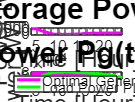

print = 1;
E_max = Storage_size(5);
day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(chosen,:);
YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset+1:end),sigma2023,mu2023,E_max,print);

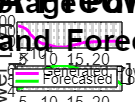

YES_shortest_on_prediction_fnc(Predictions_ARIMAX_2023_transposed(chosen,:),sigma_arima,mu_arima,E_max,print,'ARMA Prediction','Generated Power P_g(t) and Forecasted Load Power P_l(t)','Generated Power P_g','Forecasted Load Power P_L');

% 